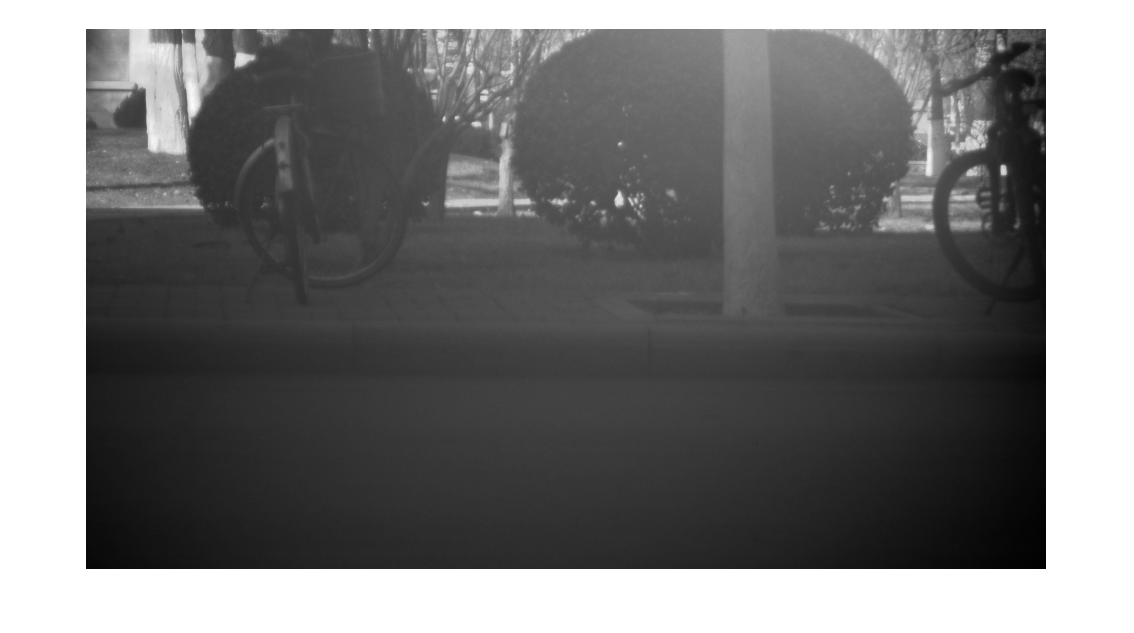

img1=imread('alpha9.bmp');
img2=imread('alpha25.bmp');
img1=rgb2gray(img1);
img2=rgb2gray(img2);
img1=im2uint8(mat2gray(img1));
img2=im2uint8(mat2gray(img2));
imshow(img1);

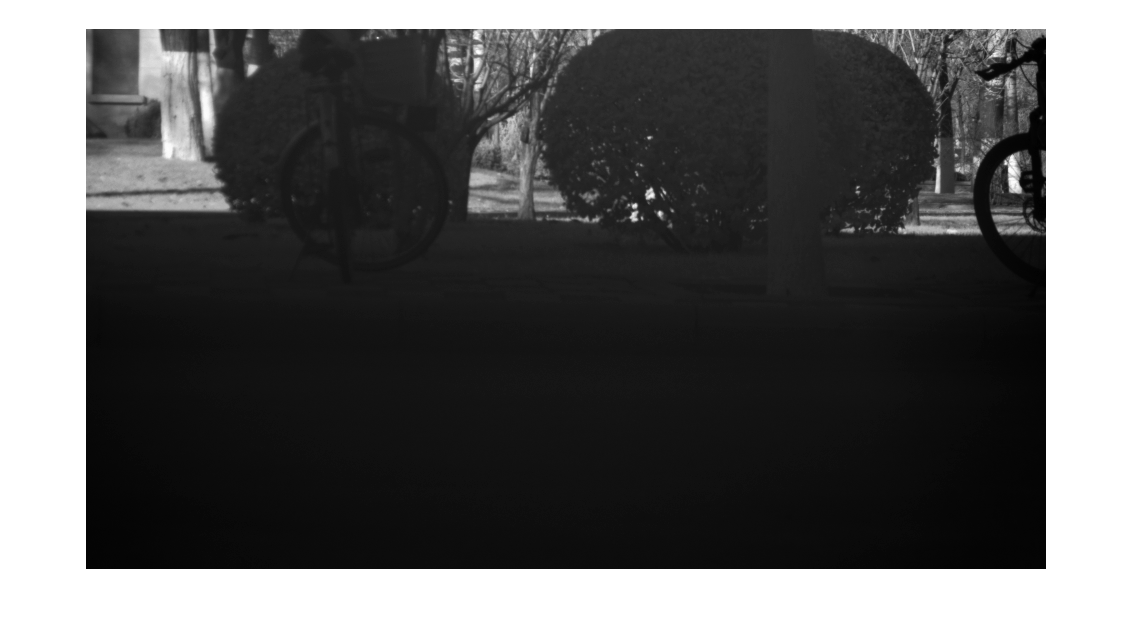

imshow(img2);

s=size(img1);
height=s(1);
width=s(2);
dif=0;

%样本框1
ref.x=82;
ref.y=44;
ref.width=67;
ref.height=47;


% %样本框2
% ref.x=759;
% ref.y=103;
% ref.width=134;
% ref.height=114;

% %样本框3
% ref.x=387;
% ref.y=165;
% ref.width=432-387;
% ref.height=208-165;


if ref.x-100<1
    offx_range1=1;
else
    offx_range1=ref.x-100;
end
if ref.x+100+ref.width>width
    offx_range2=width-ref.width;
else
    offx_range2=ref.x+100;
end
if ref.y-50<1
    offy_range1=1;
else
    offy_range1=ref.y-50;
end
if ref.y+50+ref.height>height
    offy_range2=height-ref.height;
else
    offy_range2=ref.y+50;
end
% offx_range1=1;
% offx_range2=width-ref.width;
% offy_range1=1;
% offy_range2=height-ref.height;
offx_range=offx_range2-offx_range1+1;
offy_range=offy_range2-offy_range1+1;
dif_arr=zeros(offy_range,offx_range);

for offx=offx_range1:offx_range2
    for offy=offy_range1:offy_range2
%         if offx>=0&&offy>=0
%             dif=calDif(img1 (abs(offy)+1:height,abs(offx)+1:width),img2(1:height-abs(offy),1:width-abs(offx)));
%         end
%         if offx<0&&offy<0
%             dif=calDif(img1(1:height-abs(offy),1:width-abs(offx)),img2(abs(offy)+1:height,abs(offx)+1:width));
%         end
%         if offx>=0&&offy<0
%             dif=calDif(img1(1:height-abs(offy),abs(offx)+1:width),img2(abs(offy)+1:height,1:width-abs(offx)));
%         end
%         if offx<0&&offy>=0
%             dif=calDif(img1(abs(offy)+1:height,1:width-abs(offx)),img2(1:height-abs(offy),abs(offx)+1:width));
%         end
        %这里是取图1的样本框，在图2上扫描
        dif=calDif(img1(ref.y:ref.y+ref.height,ref.x:ref.x+ref.width),img2(offy:offy+ref.height,offx:offx+ref.width));

        dif_arr(offy-offy_range1+1,offx-offx_range1+1)=dif;
    end
    %fprintf('%d,',offx);
    %fprintf('\n');
end

minor=min(min(dif_arr));
minor_pos=find(dif_arr==minor);
ref.offx=floor(minor_pos/offy_range)+1;
ref.offy=minor_pos-(ref.offx-1)*offy_range;

%最终偏差：(图2相对于图1，向右为正）
final_offx=ref.offx-ref.x+offx_range1;
final_offy=ref.offy-ref.y+offy_range1;

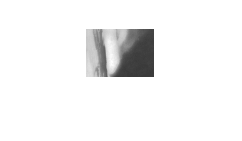

%检验修正结果：提取两幅图的两处样本区域
imshow(img1(ref.y:ref.y+ref.height,ref.x:ref.x+ref.width));

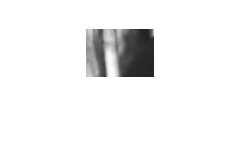

imshow(img2(ref.offy+offy_range1:ref.offy+offy_range1+ref.height,ref.offx+offx_range1:ref.offx+offx_range1+ref.width));

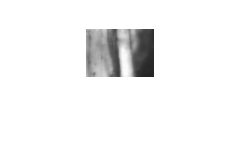


%当不进行校正的时候（两幅图使用同样坐标检索）：
%imshow(img1(ref.y:ref.y+ref.height,ref.x:ref.x+ref.width));
imshow(img2(ref.y:ref.y+ref.height,ref.x:ref.x+ref.width));